## Import Dataset

Dataset can be found at https://archive.ics.uci.edu/dataset/186/wine+quality.

data_red = readtable('winequality-red.csv');

data_white = readtable('winequality-white.csv');

## Visualise Dataset

It appears that the red wine dataset has less datapoints than the white wine dataset. This needs to be fixed to avoid a bias for white wine.

whos data_red

  Name             Size             Bytes  Class    Attributes

  data_red      1599x12            158535  table              



whos data_white

  Name               Size             Bytes  Class    Attributes

  data_white      4898x12            475239  table              



head(data_red)

    fixedAcidity    volatileAcidity    citricAcid    residualSugar    chlorides    freeSulfurDioxide    totalSulfurDioxide    density     pH     sulphates    alcohol    quality
    ____________    _______________    __________    _____________    _________    _________________    __________________    _______    ____    _________    _______    _______

         7.4              0.7                0            1.9           0.076             11                    34            0.9978     3.51      0.56         9.4         5   
         7.8             0.88                0            2.

head(data_white)

    fixedAcidity    volatileAcidity    citricAcid    residualSugar    chlorides    freeSulfurDioxide    totalSulfurDioxide    density     pH     sulphates    alcohol    quality
    ____________    _______________    __________    _____________    _________    _________________    __________________    _______    ____    _________    _______    _______

          7              0.27             0.36           20.7           0.045             45                   170             1.001        3      0.45         8.8         6   
        6.3               0.3             0.34            1.

## Preprocessing Dataset

There is no missing data in either one of the datasets.

sum(ismissing(data_red))

ans =      0     0     0     0     0     0     0     0     0     0     0     0


sum(ismissing(data_white))

ans =      0     0     0     0     0     0     0     0     0     0     0     0


### Oversampling Red Wine Dataset

To compensate for the lack of red wine datapoints, the dataset is oversampled using the mean values of the red wine datapoints. The red wine dataset is adjusted to have the same number of samples as the white wine dataset.

colMeans = varfun(@mean, data_red, 'OutputFormat', 'uniform')

colMeans =     8.3196    0.5278    0.2710    2.5388    0.0875   15.8749   46.4678    0.9967    3.3111    0.6581   10.4230    5.6360


numNewRows = height(data_white) - height(data_red)

numNewRows = 3299

extraData_red = array2table(repmat(colMeans, numNewRows, 1), 'VariableNames', data_red.Properties.VariableNames);

### Extract Features and Target

The features and target are extracted from the datasets. The features are fixedAcidity, volatileAcidity and so on and the target is wine type (0 for red wine and 1 for white wine).

data_red = [data_red; extraData_red];
data_red.type = zeros(height(data_red), 1);
data_white.type = ones(height(data_white), 1);
data = [data_red; data_white];
head(data)

    fixedAcidity    volatileAcidity    citricAcid    residualSugar    chlorides    freeSulfurDioxide    totalSulfurDioxide    density     pH     sulphates    alcohol    quality    type
    ____________    _______________    __________    _____________    _________    _________________    __________________    _______    ____    _________    _______    _______    ____

         7.4              0.7                0            1.9           0.076             11                    34            0.9978     3.51      0.56         9.4         5        0  
  

tail(data)

    fixedAcidity    volatileAcidity    citricAcid    residualSugar    chlorides    freeSulfurDioxide    totalSulfurDioxide    density     pH     sulphates    alcohol    quality    type
    ____________    _______________    __________    _____________    _________    _________________    __________________    _______    ____    _________    _______    _______    ____

        6.1              0.34             0.29            2.2           0.036             25                   100            0.98938    3.06      0.44        11.8         6        1  
  

X = table2array(data(:, 1:11));
y = table2array(data(:, 13));

## Training the Neural Network

net = patternnet([5 5])     % 2*5 neurons layers in hidden layer

net =

    Neural Network
 
              name: 'Pattern Recognition Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 3
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 35
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1; 1]
      

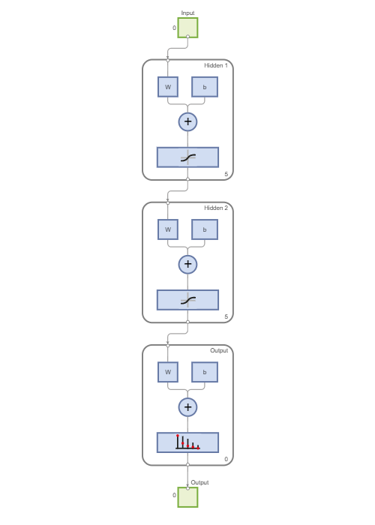

view(net)

The net is the trained DNN model with its weights and biases. The ROC curve and the confusion matrix show a very promising model with highly accurate inference.

[net, tr] = train(net, X', y');

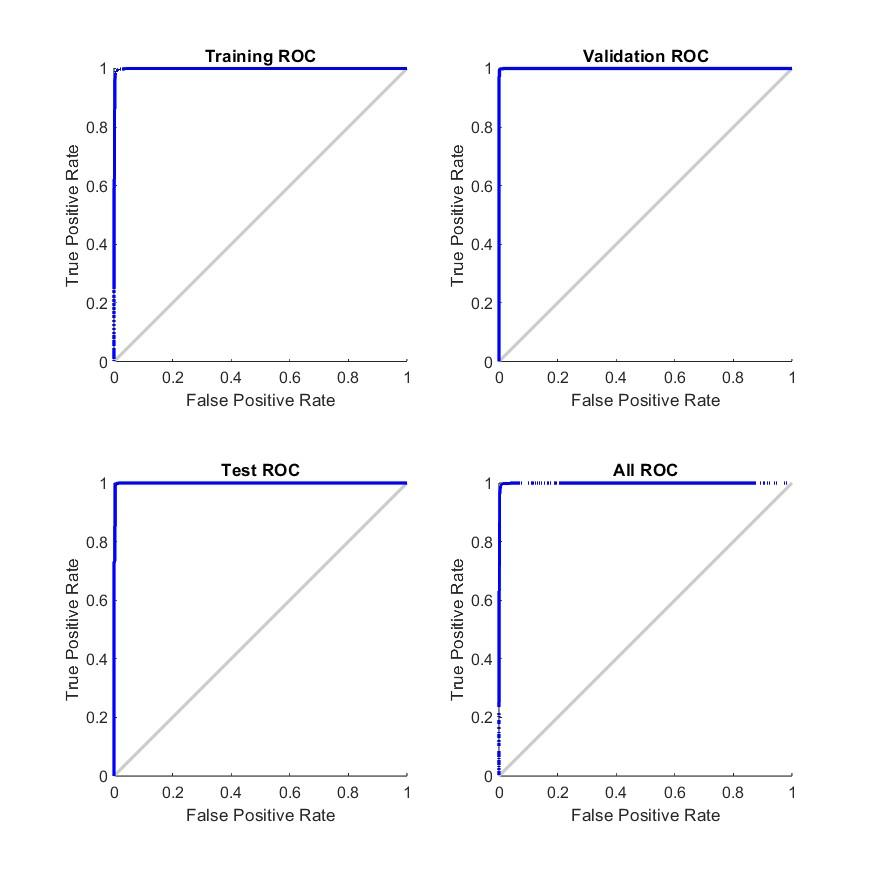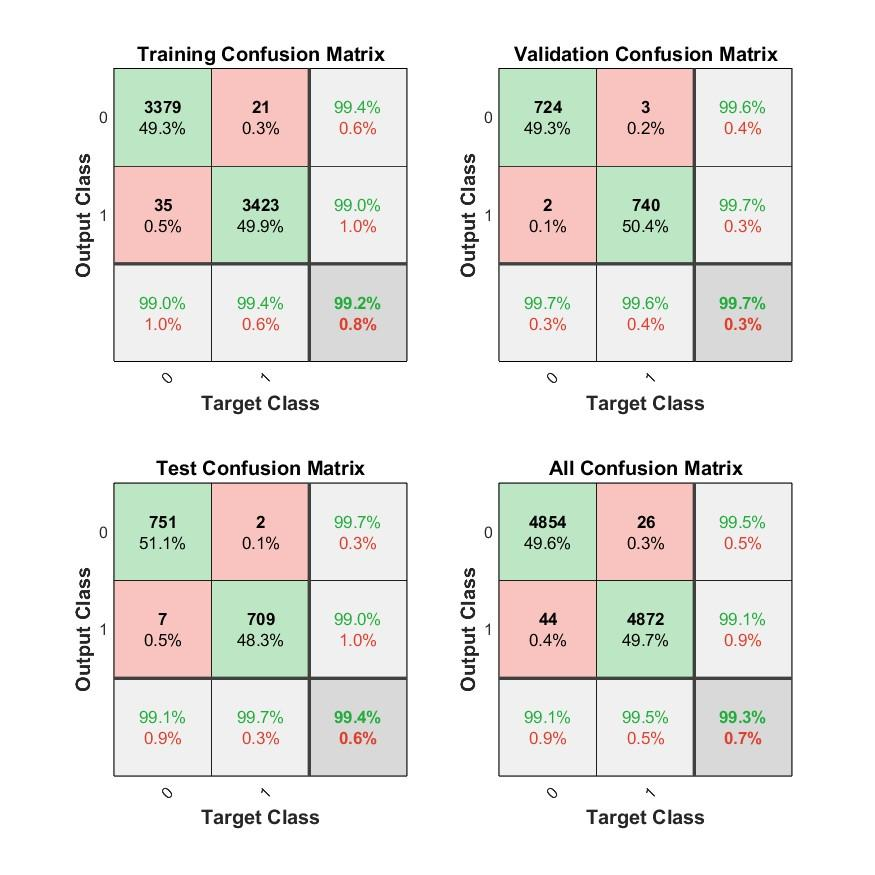

## Testing Neural Network Model

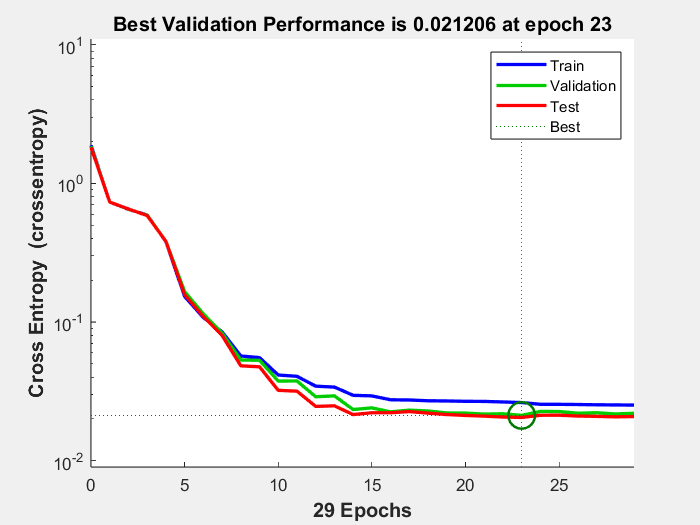

plotperform(tr)

To test the DNN model, random samples pulled from the datasets are used as inputs to the model. As expected, the model predicts all the samples highly accurately. However, a better alternative for testing would have to obtain other never seen before wine samples and feeding them into the DNN.

N = 10; % Number of rows to select
randomRows_red = data_red(randperm(height(data_red), N), :)

randomRows_red = 10×13 table
    fixedAcidity    volatileAcidity    citricAcid    residualSugar    chlorides    freeSulfurDioxide    totalSulfurDioxide    density      pH      sulphates    alcohol    quality    type
    ____________    _______________    __________    _____________    _________    _________________    __________________    _______    ______    _________    _______    _______    ____

          7.4              0.58               0              2           0.064               7                    11          0.99562      3.45        0.5

randomRows_white = data_white(randperm(height(data_white), N), :)

randomRows_white = 10×13 table
    fixedAcidity    volatileAcidity    citricAcid    residualSugar    chlorides    freeSulfurDioxide    totalSulfurDioxide    density     pH     sulphates    alcohol    quality    type
    ____________    _______________    __________    _____________    _________    _________________    __________________    _______    ____    _________    _______    _______    ____

        6.6              0.285            0.49           11.4           0.035             57                   137            0.99732    3.08      0.54     

white_test = table2array(randomRows_white(:, 1:11));
red_test = table2array(randomRows_red(:, 1:11));
sim(net, white_test')

ans =     0.9977    0.9983    0.9980    0.9782    0.9978    0.9977    0.9981    0.9984    0.9978    0.9984


sim(net, red_test')

ans = 1.0e-03 *

    0.7122    0.7364    0.4747    0.7364    0.4383    0.7364    0.5580    0.7364    0.7364    0.7364
